#                        Blind Source Separation

##                                            HW6-Section-1

                 Mohammadreza Arani         :::::::::::::         810100511

                                                           1402/02/20   

clear ; clc; close all;


## Section-1:

## 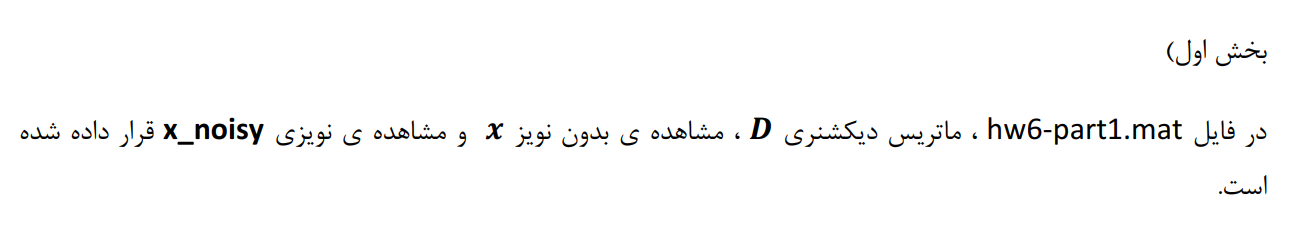               

Data_Q6_p1 = load("hw6-part1.mat"); % Load Given Data: D and x 

Dictionary_Part1 =  Data_Q6_p1.D;
X_Part1 =  Data_Q6_p1.x;
X_Noisy_Part1 =  Data_Q6_p1.x_noisy;

### Part-1:   BP (Basis Pursuit) over x (Not Noisy Data)



[M,N]=size(Dictionary_Part1);
% Linear Programming
f=ones(2*N,1);
Aeq=[Dictionary_Part1 -Dictionary_Part1];
beq=X_Part1;
lb=zeros(2*N,1);
tic;
yhat = linprog(f,[],[],Aeq,beq,lb,[]); % Linear-Programming: given Cost function: (f) + Equality Constraints with respect to Variables

Optimal solution found.




% in Matrix Form

splus=   yhat(1:N);
sminus=  yhat(N+1:end);
sBP=     splus-sminus;

posBP=find(abs(sBP)>0.01)'; % Choose Nonzero Elements
delta_t_LinP = toc;
disp("Elapsed Time (LP): "+ delta_t_LinP+"(s)");

Elapsed Time (LP): 0.051926(s)


disp('BP:')

BP:


[posBP;sBP(posBP)'] 

ans =     2.0000   10.0000
    1.0000   -2.0000


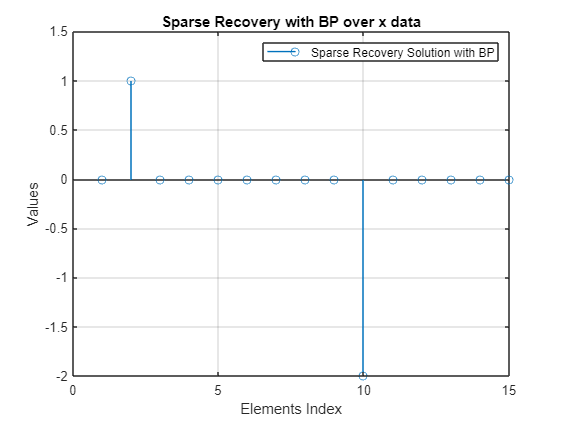

figure()
stem(sBP)
xlabel("Elements Index")
ylabel("Values")
grid on
legend("Sparse Recovery Solution with BP")
title("Sparse Recovery with BP over x data")

## Part-2: MP

xr = X_Part1;
N0 = 2;
Chosen_IDX = 100+zeros(1,N0);
Choesn_Value = Chosen_IDX;
[Row_D,Col_D] = size(Dictionary_Part1);
tic;
B = Dictionary_Part1;

for  i=1:N0
    if(i>1)
    B(:,Chosen_IDX(i-1)) = [];
    end
    Corr_matrix = repmat(xr,1,Col_D-i+1).*B;
    Corr_sum    = sum(Corr_matrix,1); % Summation for each Column -->> a Row Vector
    [Value,Idx] = max(abs(Corr_sum)); % Choosing Best Fitted
    if(sum(Idx>Chosen_IDX)>0)
        Idx  = Idx + sum(Idx>Chosen_IDX) ;
    end
    Chosen_IDX(i)   =  Idx;
    Choesn_Value(i) = Value;
    xr = X_Part1 - Value*Dictionary_Part1(:,Idx); % xr = x  - <x,di>di
end
delta_t_MP = toc;
sMP = zeros(1,Col_D);
sMP(1,Chosen_IDX) = Choesn_Value;
disp("Elapsed Time (MP): "+ delta_t_MP+"(s)");

Elapsed Time (MP): 0.0054995(s)


disp(" Best Indices Are ")

 Best Indices Are 


disp(Chosen_IDX)

    10     2



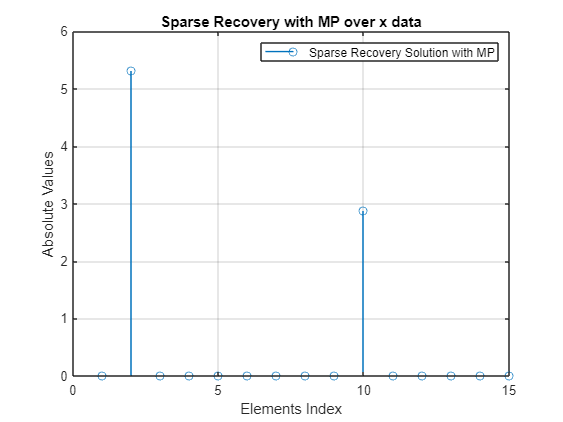

figure()
stem( sMP)
xlabel("Elements Index")
ylabel("Absolute Values")
grid on
legend("Sparse Recovery Solution with MP")
title("Sparse Recovery with MP over x data")

## Part-3: BP over Noisy Data


[M,N]=size(Dictionary_Part1);
% Linear Programming
f=ones(2*N,1);
Aeq=[Dictionary_Part1 -Dictionary_Part1];
beq=X_Noisy_Part1;
lb=zeros(2*N,1);
tic;
yhat_Noisy = linprog(f,[],[],Aeq,beq,lb,[]); % Linear-Programming: given Cost function: (f) + Equality Constraints with respect to Variables

Optimal solution found.




% in Matrix Form

splus_Noisy=   yhat_Noisy(1:N);
sminus_Noisy=  yhat_Noisy(N+1:end);
sBP_Noisy=     splus_Noisy-sminus_Noisy;

posBP_Noisy=find(abs(sBP_Noisy)>0.01)'; % Choose Nonzero Elements
delta_t_LinP = toc;
disp("Elapsed Time (LP): "+ delta_t_LinP+"(s)");

Elapsed Time (LP): 0.16902(s)


disp('BP:')

BP:


[posBP_Noisy;sBP_Noisy(posBP_Noisy)'] 

ans =     2.0000    3.0000    5.0000   10.0000   11.0000
    0.9013    0.1304   -0.2066   -1.9396    0.0148


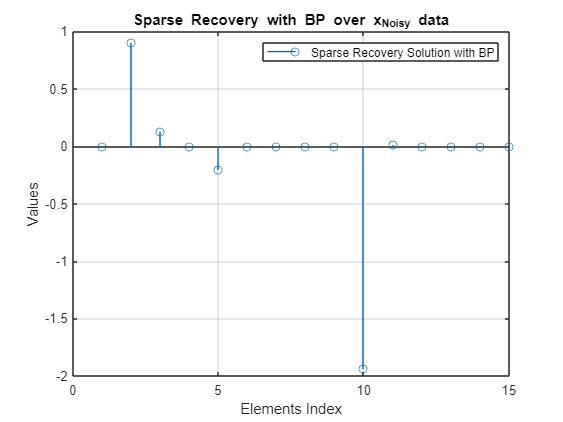

figure()
stem(sBP_Noisy)
xlabel("Elements Index")
ylabel("Values")
grid on
legend("Sparse Recovery Solution with BP")
title("Sparse Recovery with BP over x_{Noisy} data")

## Part-4: LASSO (Least Absolute Shrinkage and selection Operator): with Convex Optimization

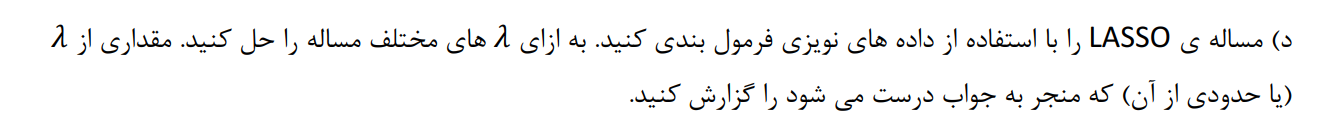



% Convex Optimization:

Lambda_Vec = [ 1e-8 , 1e-7, 1e-6 , 1e-5, 2e-5, 5e-5 , 8e-5 ,1e-4, 3e-4, 5e-4, 8e-4 ,1e-3, 1e-2, 2e-2,5e-2,8e-2 ,...
               1e-1, 2e-1, 5e-1, 8e-1, 9e-1, 9.5e-1 ,1 , 1e01 , 1e02 , 1e03 ];
Sparsity_Level = zeros(1,length(Lambda_Vec));
SParse_Values = cell(1,length(Lambda_Vec));
SparseIndices = SParse_Values;

for i=1:length(Lambda_Vec)
    lambda_COnvex = Lambda_Vec(i);
    
    % Set up and solve the LASSO problem using CVX
    cvx_begin quiet
        variable s_Convex(N) 
        minimize(  norm(X_Noisy_Part1 - Dictionary_Part1* s_Convex, 2) + lambda_COnvex * norm(s_Convex, 1)   )
    cvx_end
    
    % Print the results
    % disp(cvx_optval)
    % disp(s_Convex(abs(s_Convex)>1e-3))
    Sparsity_Level(i)  = length(s_Convex(abs(s_Convex)>1e-1));
    SParse_Values{1,i} =  s_Convex;
    SparseIndices{1,i} =  find( abs(s_Convex)>1e-1  );
    clear s_Convex;

end


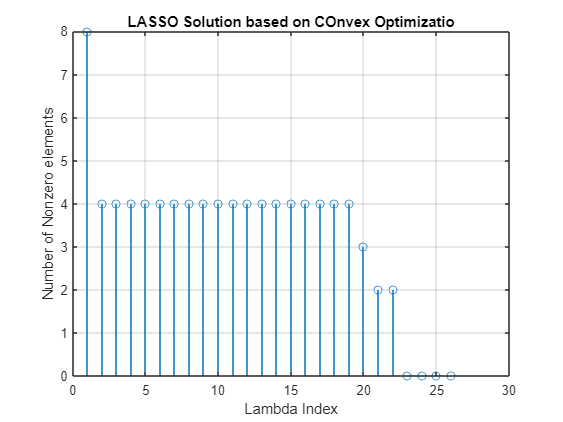

figure()
stem(Sparsity_Level)
grid on
xlabel("Lambda Index");
ylabel("Number of Nonzero elements")
title("LASSO Solution based on COnvex Optimizatio")

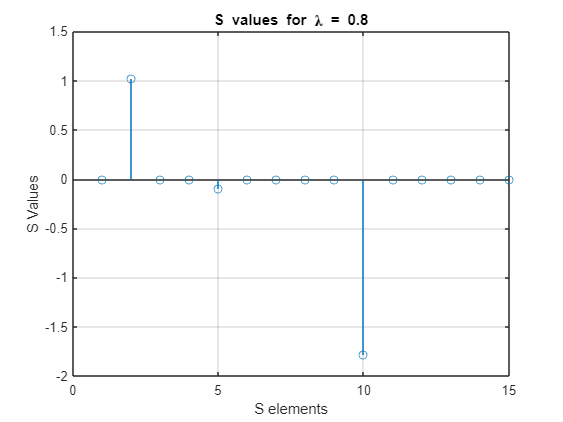

Index_to_Show_Lambda = 20;
figure()
stem(SParse_Values{1,Index_to_Show_Lambda})
grid on
xlabel("S elements")
ylabel("S Values")
title("S values for \lambda = "+Lambda_Vec(Index_to_Show_Lambda))

## Part-4: LASSO (Least Absolute Shrinkage and selection Operator): with Alternation Minimization

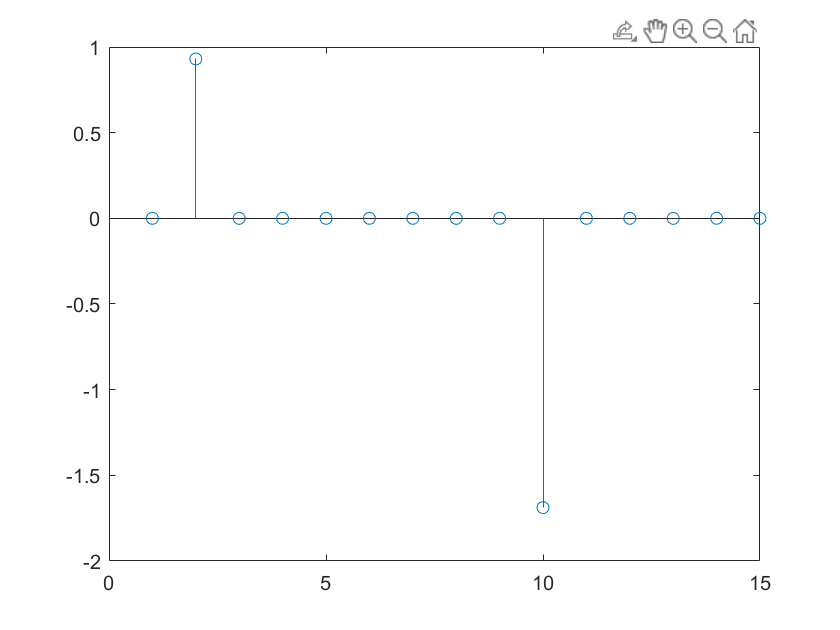

% Update each S for different Iterations:

IterMax = 20;
[M,N]=size(Dictionary_Part1);
s_Alter = ones(1,N);
Lambda_Alter  =8e-1;

for i=1:IterMax
    for Indice = 1:length(s_Alter)
        d_i               =           Dictionary_Part1(:,Indice);
        indices_Chosen    = 1:length(s_Alter);
        indices_Chosen(Indice) = [] ;
        d_n               = Dictionary_Part1(:,indices_Chosen);
        s_n               = s_Alter(1,indices_Chosen)';

        r_i = X_Noisy_Part1 - d_n*s_n;
        RHO = r_i'*d_i;
        s_Alter(Indice) = My_soft(RHO, Lambda_Alter/2) ;
        drawnow
        stem(s_Alter)
    end

end

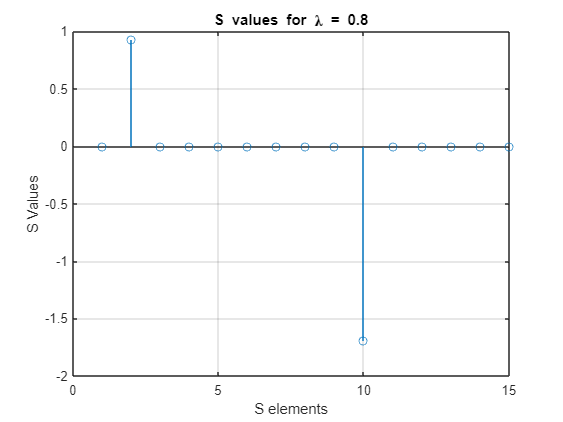




figure()
stem(s_Alter)
grid on
xlabel("S elements")
ylabel("S Values")
title("S values for \lambda = "+Lambda_Alter   )

function out = My_soft(a,b)

if(length(a)>1)
    out = zeros(size(a));
    outside_idx = a <= -b/2 | a >= b/2;
    out(outside_idx) = a(outside_idx) - sign(a(outside_idx))*b/2;
    out(~outside_idx) = 0;
else
    out = 0;
    if( a < -abs(b))
        out = a + abs(b) ;
    elseif (a > abs(b))
        out = a - abs(b); 
    end

end

end




